## make movie

clear mov
fr(1:length(us(1,1,:))) = struct('cdata',[],'colormap',[]);
figure(1)

for i = 1: length(us(1,1,:))
    imagesc(x_grid*1000,y_grid*1000,us(:,:,i));
    colorbar;
    axis equal;
    axis tight;
    
    set(gca,'YDir','normal','FontSize',14);
    xlabel('x方向[mm]','FontSize',14)
    ylabel('y方向[mm]','FontSize',14)
    caxis([1350 1600])
    c = colorbar;
    c.Label.String = '[m/s]';
    pause(0.05);
    
    fr(i) = getframe(1);
    drawnow;
end

## play movie

figure;
movie(fr,1,3)

## save movie

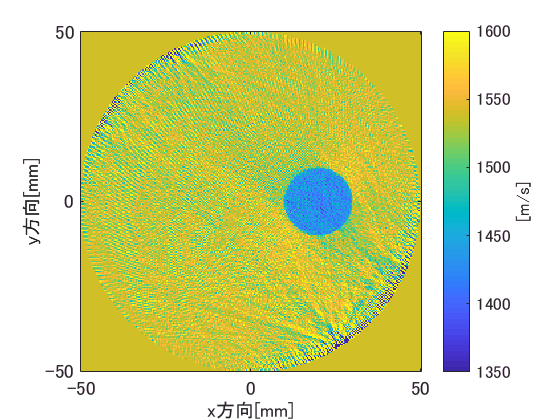

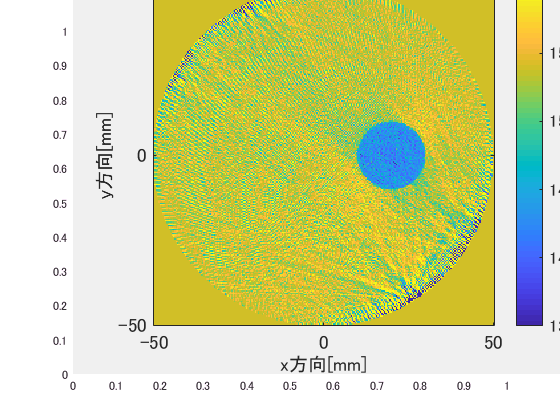

cd('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\result\ART_validate')
mv = VideoWriter('2018_02_27_ART_iteration_movie','MPEG-4');
mv.FrameRate = 3; % ← fpsと同じ
open(mv)
writeVideo(mv,fr)
close(mv)